# IMPORT

Ankle_01=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-001.csv');
Ankle_02=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-002.csv');
Ankle_03=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-003.csv');
Ankle_04=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-004.csv');
Ankle_05=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-005.csv');
Ankle_06=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-006.csv');
Ankle_07=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-007.csv');
Ankle_08=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-008.csv');

## CODE ANKLE 01

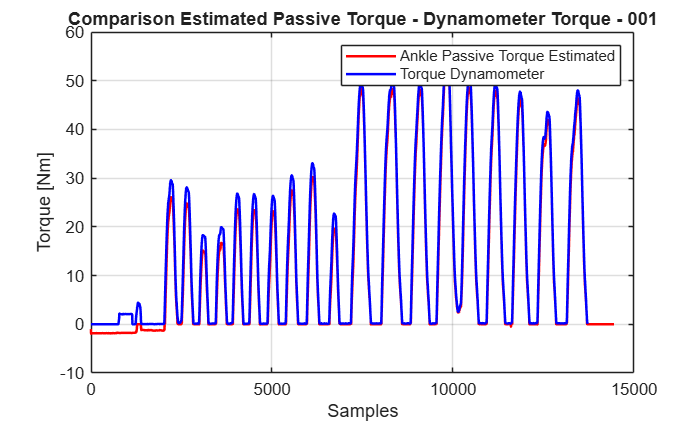

Fz_Ankle01_tab=Ankle_01(2:144491,5); 
LeverArm_Ankle01_tab=Ankle_01(144497:end,3);
Fz_Ankle01_original=table2array(Fz_Ankle01_tab);
LeverArm_Ankle01=table2array(LeverArm_Ankle01_tab); 

Fz_Ankle01=resample(Fz_Ankle01_original, 100, 1000);
LeverArm_Ankle01=LeverArm_Ankle01./1000; % mm to meters
Torque_computed_Ankle01=Fz_Ankle01.*LeverArm_Ankle01;

Torque_dynamometer_original = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\001.cxp",...
    'FileType','text');
Torque_dynamometer=Torque_dynamometer_original(:,1);
Torque_dynamometer_100Hz_01 = resample(Torque_dynamometer, 100, 256);

N = 780; % samples for the shift
Torque_dynamometer_shifted = [zeros(N,1); Torque_dynamometer_100Hz_01];

close all;
plot(-Torque_computed_Ankle01,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_shifted,'b','LineWidth',1.5);
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 001');
grid on;

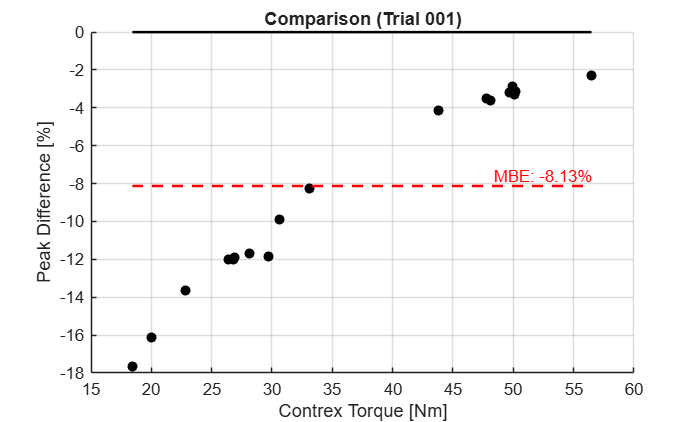

Torque_computed_Ankle01_Clean = abs(Torque_computed_Ankle01); 
Torque_dynamometer_shifted_Clean = abs(Torque_dynamometer_shifted);

min_len = min(length(Torque_computed_Ankle01_Clean), length(Torque_dynamometer_shifted_Clean));
T_Est = Torque_computed_Ankle01_Clean(1:min_len); 
T_Dyn = Torque_dynamometer_shifted_Clean(1:min_len); 

% Peak Identification (using the Dynamometer curve as the reference)

[pks_dyn, locs_dyn] = findpeaks(T_Dyn, 'MinPeakHeight', 10, 'MinPeakDistance', 120);
pks_est = T_Est(locs_dyn); 

% Filtering
valid_indices = pks_est > 0 & pks_dyn > 0;
Pks_Dyn_Final = pks_dyn(valid_indices);
Pks_Est_Final = pks_est(valid_indices);

% Difference: (Computed - Dynamo)
Peak_Difference = Pks_Est_Final - Pks_Dyn_Final; 

% Y-Axis: Percentage difference compared to the dynamometer (reference)
% Equation: (Estimated - Dynamo) / Dynamo * 100
Error_Percentage_Y = (Peak_Difference ./ Pks_Dyn_Final)  * 100;  

% X-Axis : Dynamo Torque [Nm]
Dynamometer_Torque_X = Pks_Dyn_Final;

figure;
scatter(Dynamometer_Torque_X, Error_Percentage_Y, 'k', 'filled'); 
hold on;
plot([min(Dynamometer_Torque_X) max(Dynamometer_Torque_X)], [0 0], 'k-', 'LineWidth', 1.5); 

% Mean Bias Error (MBE)
MBE = mean(Error_Percentage_Y);
plot([min(Dynamometer_Torque_X) max(Dynamometer_Torque_X)], [MBE MBE], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 001)');
grid on;
text(max(Dynamometer_Torque_X), MBE, sprintf('MBE: %.2f%%', MBE), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX

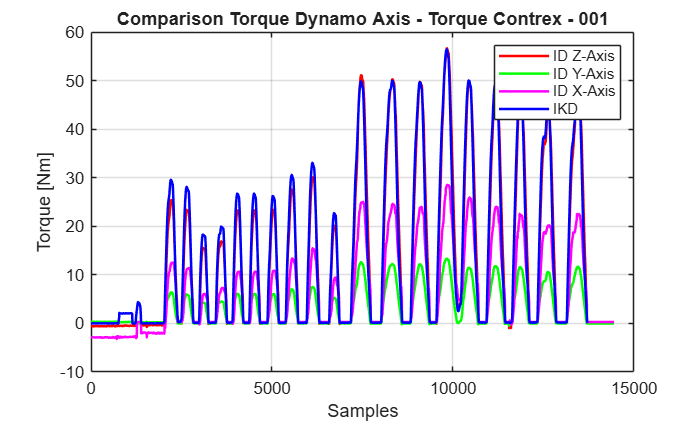

Ankle_0101=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-001001.csv');
Ankle_0202=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-002002.csv');
Ankle_0808_1=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle_008008_1.csv');
Ankle_0808_2=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle_008008_2.csv');

Torque_GRF_0101_x=Ankle_0101(3:end-1,3);
Torque_GRF_0101_y=Ankle_0101(3:end-1,4);
Torque_GRF_0101_z=Ankle_0101(3:end-1,5);
Torque_GRF_01_x=table2array(Torque_GRF_0101_x);
Torque_GRF_01_y=table2array(Torque_GRF_0101_y);
Torque_GRF_01_z=table2array(Torque_GRF_0101_z);

close all;
plot(Torque_GRF_01_z,'r','LineWidth',1.5);
hold on;
plot(Torque_GRF_01_y,'g','LineWidth',1.5);
plot(Torque_GRF_01_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_shifted,'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 001');
grid on;

## ANKLE ANGLE DATA + GRAVITATIONAL COMPONENT REMOVAL

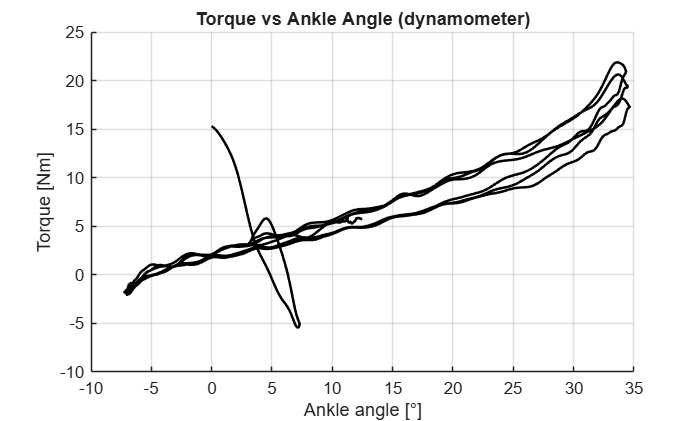

Passive_Contrex_Max=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Max_passive_contrex.csv');

AnkleAngle_dynamo_Max=Passive_Contrex_Max{62767:end,5};
AnkleAngle_dynamo_Max=AnkleAngle_dynamo_Max-AnkleAngle_dynamo_Max(1);
Torque_dynamo_Max_original=Passive_Contrex_Max{2:62761,21};

% FILTERING LP 5 Hz

low_pass_cutoff = 5; 
nyq_f = 1500 / 2;  
lpWn = low_pass_cutoff / nyq_f;  
order = 4;
[bpB, bpA] = butter(order, lpWn, 'low');
Torque_dynamo_filt_Max = filtfilt(bpB, bpA, Torque_dynamo_Max_original); 

Torque_dynamo_Max=zeros(length(AnkleAngle_dynamo_Max),1);
for i = 1:length(AnkleAngle_dynamo_Max)
    idx_start = (i-1)*15 + 1;
    idx_end   = i*15;
    Torque_dynamo_Max (i) = mean(Torque_dynamo_filt_Max(idx_start:idx_end));
end

% --- Plot Torque vs Ankle Angle ---
figure; hold on; grid on;
plot(AnkleAngle_dynamo_Max, Torque_dynamo_Max, 'k', 'LineWidth', 1.5);

xlabel('Ankle angle [°]');
ylabel('Torque [Nm]');
title('Torque vs Ankle Angle (dynamometer)');

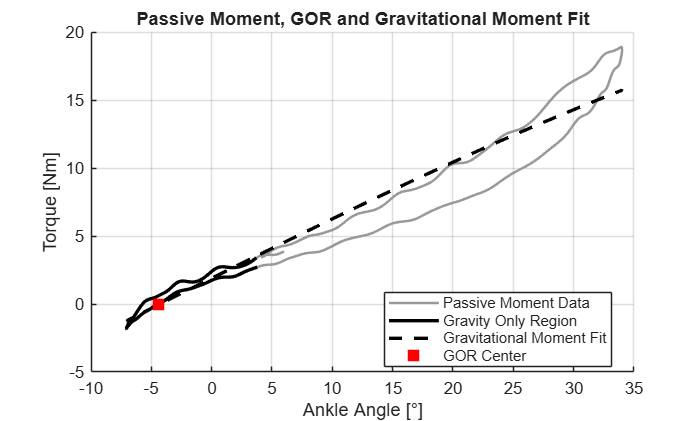

AnkleAngle_dynamo_Max_1=AnkleAngle_dynamo_Max(190:1390);
Torque_dynamo_Max_1=Torque_dynamo_Max(190:1390);
AnkleAngle_dynamo_Max_2=AnkleAngle_dynamo_Max(1390:2590);
Torque_dynamo_Max_2=Torque_dynamo_Max(1390:2590);
AnkleAngle_dynamo_Max_3=AnkleAngle_dynamo_Max(2590:3790);
Torque_dynamo_Max_3=Torque_dynamo_Max(2590:3790);

AnkleAngle_dynamo_Max_all = [AnkleAngle_dynamo_Max_1, AnkleAngle_dynamo_Max_2, AnkleAngle_dynamo_Max_3];
Torque_dynamo_Max_all = [Torque_dynamo_Max_1, Torque_dynamo_Max_2, Torque_dynamo_Max_3];

Mean_AnkleAngle_dynamo_Max = mean(AnkleAngle_dynamo_Max_all, 2);
Mean_Torque_dynamo_Max = mean(Torque_dynamo_Max_all, 2);

% CUBIC POLYNOMIAL FIT
p_Max = polyfit(Mean_AnkleAngle_dynamo_Max, Mean_Torque_dynamo_Max, 3);
a1_Max = p_Max(1);
a2_Max = p_Max(2);
a3_Max = p_Max(3);
a4_Max = p_Max(4);
F_poly_Max = [a1_Max, a2_Max, (6*a1_Max + a3_Max), (2*a2_Max + a4_Max)];
roots_F_Max = roots(F_poly_Max);
ROM_min_Max = min(Mean_AnkleAngle_dynamo_Max);
ROM_max_Max = max(Mean_AnkleAngle_dynamo_Max);
GOR_center_Max=roots_F_Max(3);

ROM_length_Max=ROM_max_Max-ROM_min_Max;
GOR_span_Max=0.4*ROM_length_Max;
GOR_min_Max=GOR_center_Max-GOR_span_Max/2;
GOR_max_Max=GOR_center_Max+GOR_span_Max/2;

% --- 1. Data isolation within the GOR ---
idx_GOR_Max = Mean_AnkleAngle_dynamo_Max >= GOR_min_Max & Mean_AnkleAngle_dynamo_Max <= GOR_max_Max;

theta_GOR_Max = Mean_AnkleAngle_dynamo_Max(idx_GOR_Max);
Torque_GOR_Max = Mean_Torque_dynamo_Max(idx_GOR_Max);
theta_rad_Max = deg2rad(theta_GOR_Max);

% --- 3. Regression Matrix ---
X_Max = [sin(theta_rad_Max), cos(theta_rad_Max)];

A_Max = X_Max \ Torque_GOR_Max;       % solution LS
A1_Max = A_Max(1);
A2_Max = A_Max(2);
MG_Max=A1_Max*sin(theta_rad_Max)+A2_Max*cos(theta_rad_Max);

figure; 
hold on; 
grid on;

% --- 1. Passive Curve (grey) ---
plot(Mean_AnkleAngle_dynamo_Max, Mean_Torque_dynamo_Max, ...
    'Color', [0.6 0.6 0.6], 'LineWidth', 1.5);

% --- 2. GOR (black) ---
plot(theta_GOR_Max, Torque_GOR_Max, 'k', 'LineWidth', 2);

% --- 3. Gravitational Moment Fit --> Entire ROM 
theta_full_rad_Max = deg2rad(Mean_AnkleAngle_dynamo_Max);
MG_full_Max = A1_Max .* sin(theta_full_rad_Max) + A2_Max .* cos(theta_full_rad_Max);

plot(Mean_AnkleAngle_dynamo_Max, MG_full_Max, '--k', 'LineWidth', 2);
plot(GOR_center_Max, A1_Max*sin(deg2rad(GOR_center_Max)) + A2_Max*cos(deg2rad(GOR_center_Max)),...
    'rs', 'MarkerFaceColor', 'r', 'MarkerSize', 8);
xlabel('Ankle Angle [°]');
ylabel('Torque [Nm]');
title('Passive Moment, GOR and Gravitational Moment Fit');
legend('Passive Moment Data', ...
       'Gravity Only Region', ...
       'Gravitational Moment Fit', ...
       'GOR Center', ...
       'Location', 'best');
hold off;

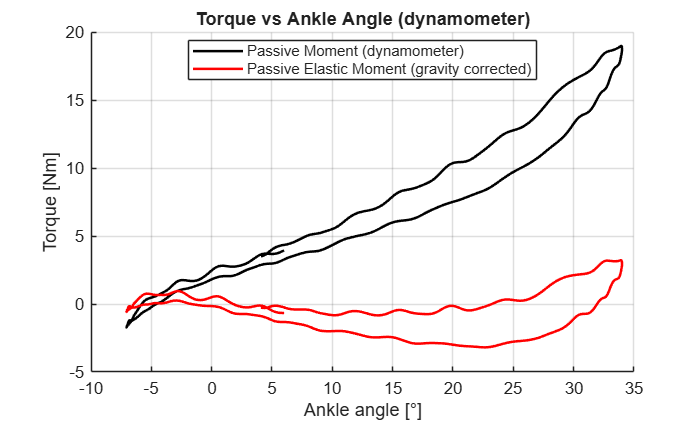

MPE_full_Max = Mean_Torque_dynamo_Max - MG_full_Max;

Torque_at_GOR_Max = - 0.0717983;
Torque_shifted_Max = Mean_Torque_dynamo_Max - Torque_at_GOR_Max;

% --- Plot Torque vs Ankle Angle ---
figure; 
hold on;
grid on;
plot(Mean_AnkleAngle_dynamo_Max, Torque_shifted_Max, 'k', 'LineWidth', 1.5); 
plot(Mean_AnkleAngle_dynamo_Max, MPE_full_Max, 'r', 'LineWidth', 1.5); 
xlabel('Ankle angle [°]');
ylabel('Torque [Nm]');
title('Torque vs Ankle Angle (dynamometer)');
legend('Passive Moment (dynamometer)', ...
       'Passive Elastic Moment (gravity corrected)', ...
       'Location', 'best');
hold off;

## CODE ANKLE 02

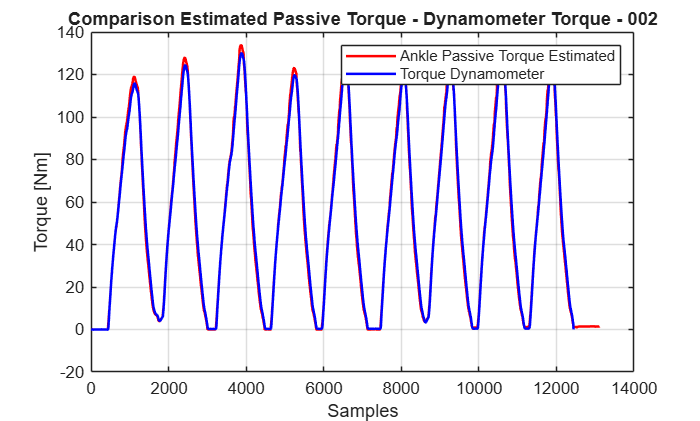

Fz_Ankle02_tab=Ankle_02(2:131071,5); 
LeverArm_Ankle02_tab=Ankle_02(131077:end,3);
Fz_Ankle02_original=table2array(Fz_Ankle02_tab); 
LeverArm_Ankle02=table2array(LeverArm_Ankle02_tab); 

Fz_Ankle02=resample(Fz_Ankle02_original, 100, 1000);

LeverArm_Ankle02=LeverArm_Ankle02./1000; 
Torque_computed_Ankle02=Fz_Ankle02.*LeverArm_Ankle02;

Torque_dynamometer_original_02 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\002.cxp",...
    'FileType','text');
Torque_dynamometer_02=Torque_dynamometer_original_02(:,1);
Torque_dynamometer_100Hz_02 = resample(Torque_dynamometer_02, 100, 256);

close all;
plot(-Torque_computed_Ankle02,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_100Hz_02(820:end),'b','LineWidth',1.5);
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 002');
grid on;

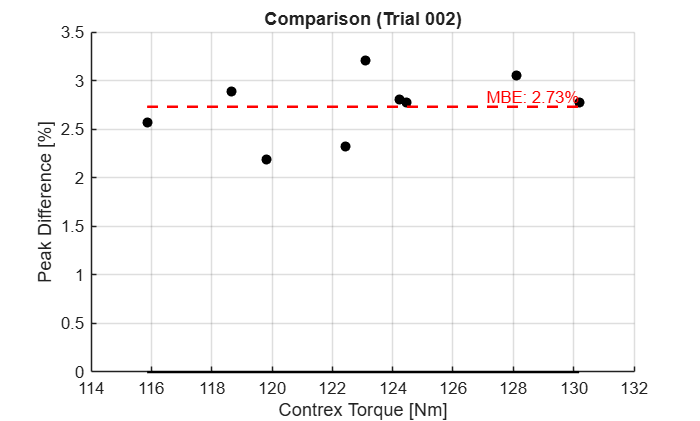

Torque_computed_Ankle02_Clean = abs(Torque_computed_Ankle02); 
Torque_dynamometer_100Hz_02_clean = abs(Torque_dynamometer_100Hz_02(820:end));

min_len_02 = min(length(Torque_computed_Ankle02_Clean), length(Torque_dynamometer_100Hz_02_clean));
T_Est_02 = Torque_computed_Ankle02_Clean(1:min_len_02); 
T_Dyn_02 = Torque_dynamometer_100Hz_02_clean(1:min_len_02); 

[pks_dyn_02, locs_dyn_02] = findpeaks(T_Dyn_02, 'MinPeakHeight', 100, 'MinPeakDistance', 1100); 
pks_est_02 = T_Est_02(locs_dyn_02); 

valid_indices_02 = pks_est_02 > 0 & pks_dyn_02 > 0;
Pks_Dyn_Final_02 = pks_dyn_02(valid_indices_02);
Pks_Est_Final_02 = pks_est_02(valid_indices_02);

Peak_Difference_02 = Pks_Est_Final_02 - Pks_Dyn_Final_02; 
Error_Percentage_Y_02 = (Peak_Difference_02 ./ Pks_Dyn_Final_02)  * 100;  
Dynamometer_Torque_X_02 = Pks_Dyn_Final_02;

figure;
scatter(Dynamometer_Torque_X_02, Error_Percentage_Y_02, 'k', 'filled'); 
hold on;
plot([min(Dynamometer_Torque_X_02) max(Dynamometer_Torque_X_02)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_02 = mean(Error_Percentage_Y_02);
plot([min(Dynamometer_Torque_X_02) max(Dynamometer_Torque_X_02)], [MBE_02 MBE_02], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 002)');
grid on;
text(max(Dynamometer_Torque_X_02), MBE_02, sprintf('MBE: %.2f%%', MBE_02), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX

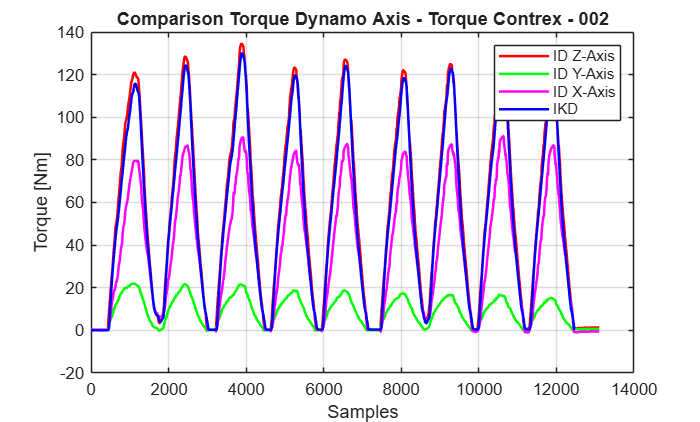

Torque_GRF_0202_x=Ankle_0202(3:end-1,3);
Torque_GRF_0202_y=Ankle_0202(3:end-1,4);
Torque_GRF_0202_z=Ankle_0202(3:end-1,5);
Torque_GRF_02_x=table2array(Torque_GRF_0202_x);
Torque_GRF_02_y=table2array(Torque_GRF_0202_y);
Torque_GRF_02_z=table2array(Torque_GRF_0202_z);

close all;
plot(Torque_GRF_02_z,'r','LineWidth',1.5);
hold on;
plot(Torque_GRF_02_y,'g','LineWidth',1.5);
plot(Torque_GRF_02_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_100Hz_02(805:end),'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 002');
grid on;

## CODE ANKLE 03

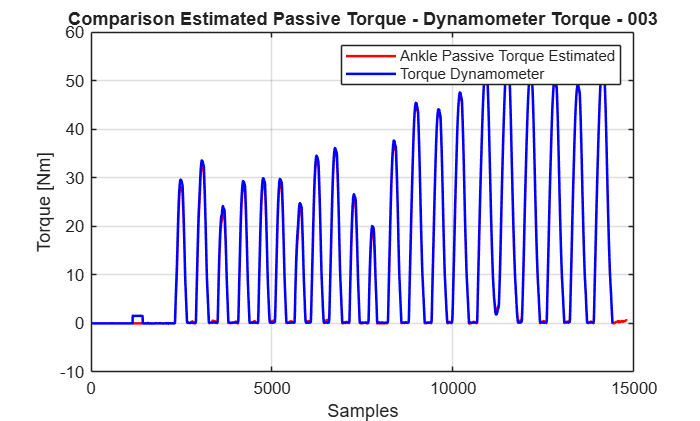

Fz_Ankle03_tab=Ankle_03(2:147911,5); 
LeverArm_Ankle03_tab=Ankle_03(147917:end,3);
Fz_Ankle03_original=table2array(Fz_Ankle03_tab); 
LeverArm_Ankle03=table2array(LeverArm_Ankle03_tab); 

Fz_Ankle03=resample(Fz_Ankle03_original, 100, 1000);

LeverArm_Ankle03=LeverArm_Ankle03./1000;
Torque_computed_Ankle03=Fz_Ankle03.*LeverArm_Ankle03;

Torque_dynamometer_original_03 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\003.cxp",...
    'FileType','text');
Torque_dynamometer_03=Torque_dynamometer_original_03(:,1);
Torque_dynamometer_100Hz_03 = resample(Torque_dynamometer_03, 100, 256);

N_03 = 1150; % samples for shift
Torque_dynamometer_shifted_03 = [zeros(N_03,1); Torque_dynamometer_100Hz_03];

close all;
plot(-Torque_computed_Ankle03,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_shifted_03,'b','LineWidth',1.5); 
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 003');
grid on;

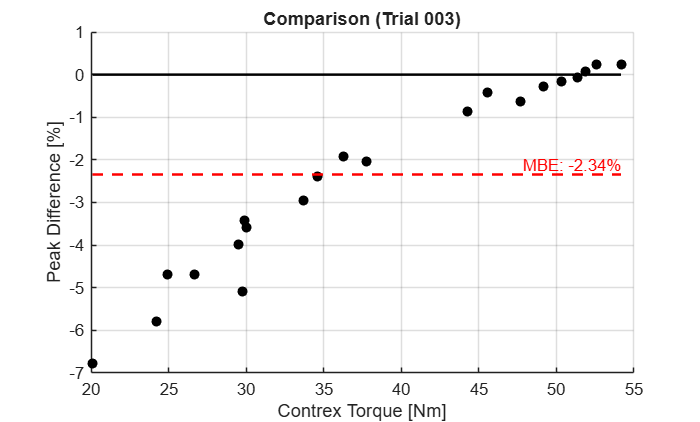

Torque_computed_Ankle03_Clean = abs(Torque_computed_Ankle03); 
Torque_dynamometer_shifted_03_clean = abs(Torque_dynamometer_shifted_03);

min_len_03 = min(length(Torque_computed_Ankle03_Clean), length(Torque_dynamometer_shifted_03_clean));
T_Est_03 = Torque_computed_Ankle03_Clean(1:min_len_03); 
T_Dyn_03 = Torque_dynamometer_shifted_03_clean(1:min_len_03); 

[pks_dyn_03, locs_dyn_03] = findpeaks(T_Dyn_03, 'MinPeakHeight', 15, 'MinPeakDistance', 400); 
pks_est_03 = T_Est_03(locs_dyn_03); 

valid_indices_03 = pks_est_03 > 0 & pks_dyn_03 > 0;
Pks_Dyn_Final_03 = pks_dyn_03(valid_indices_03);
Pks_Est_Final_03 = pks_est_03(valid_indices_03);

Peak_Difference_03 = Pks_Est_Final_03 - Pks_Dyn_Final_03; 
Error_Percentage_Y_03 = (Peak_Difference_03 ./ Pks_Dyn_Final_03)  * 100;  
Dynamometer_Torque_X_03 = Pks_Dyn_Final_03;

figure;
scatter(Dynamometer_Torque_X_03, Error_Percentage_Y_03, 'k', 'filled'); 
hold on;
plot([min(Dynamometer_Torque_X_03) max(Dynamometer_Torque_X_03)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_03 = mean(Error_Percentage_Y_03);
plot([min(Dynamometer_Torque_X_03) max(Dynamometer_Torque_X_03)], [MBE_03 MBE_03], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 003)');
grid on;
text(max(Dynamometer_Torque_X_03), MBE_03, sprintf('MBE: %.2f%%', MBE_03), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX - 03

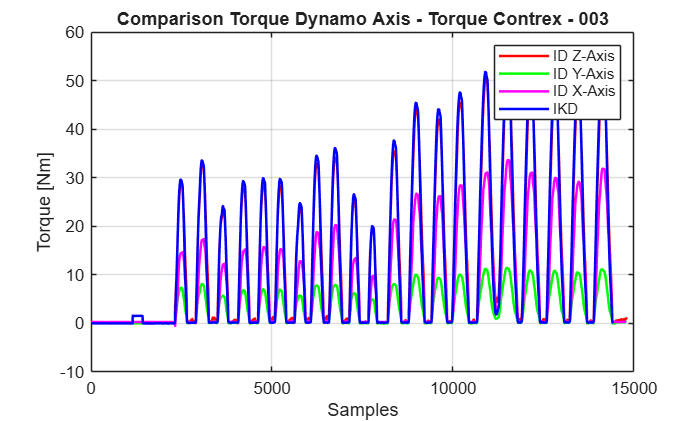

Ankle_0303=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-003003.csv');
Ankle_0404=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-4.csv');
Ankle_0505=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-5.csv');
Ankle_0606=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-6.csv');
Ankle_0707=readtable('C:\Users\gabri\OneDrive\Desktop\HUS\Ankle-7.csv');

Torque_GRF_0303_x=Ankle_0303(3:end-1,3);
Torque_GRF_0303_y=Ankle_0303(3:end-1,4);
Torque_GRF_0303_z=Ankle_0303(3:end-1,5);
Torque_GRF_03_x=table2array(Torque_GRF_0303_x);
Torque_GRF_03_y=table2array(Torque_GRF_0303_y);
Torque_GRF_03_z=table2array(Torque_GRF_0303_z);

close all;
plot(Torque_GRF_03_z,'r','LineWidth',1.5);
hold on
plot(Torque_GRF_03_y,'g','LineWidth',1.5);
plot(Torque_GRF_03_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_shifted_03,'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 003');
grid on;

## CODE ANKLE 04

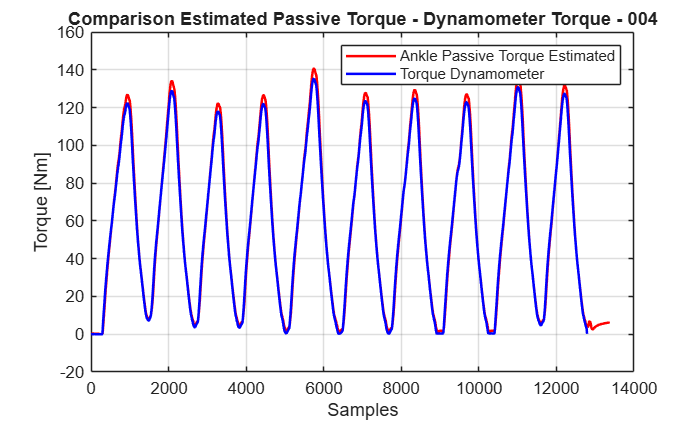

Fz_Ankle04_tab=Ankle_04(2:133551,5); 
LeverArm_Ankle04_tab=Ankle_04(133557:end,3);
Fz_Ankle04_original=table2array(Fz_Ankle04_tab); 
LeverArm_Ankle04=table2array(LeverArm_Ankle04_tab); 

Fz_Ankle04=resample(Fz_Ankle04_original, 100, 1000);

LeverArm_Ankle04=LeverArm_Ankle04./1000; 
Torque_computed_Ankle04=Fz_Ankle04.*LeverArm_Ankle04;

Torque_dynamometer_original_04 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\004.cxp",...
    'FileType','text');
Torque_dynamometer_04=Torque_dynamometer_original_04(:,1);
Torque_dynamometer_100Hz_04 = resample(Torque_dynamometer_04, 100, 256);

close all;
plot(-Torque_computed_Ankle04,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_100Hz_04(1000:end),'b','LineWidth',1.5); 
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 004');
grid on;

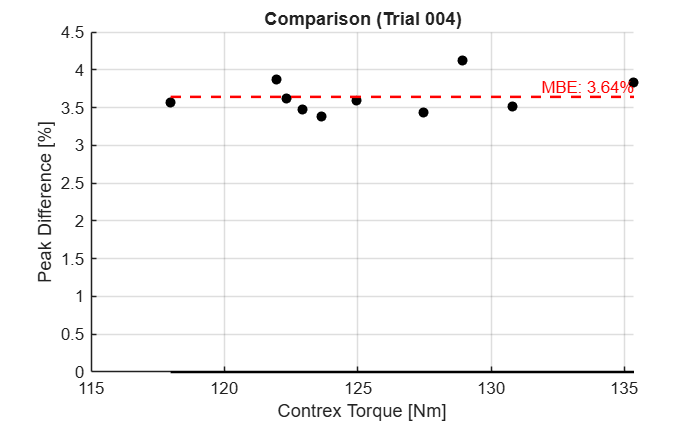

Torque_computed_Ankle04_Clean = abs(Torque_computed_Ankle04);
Torque_dynamometer_100Hz_04_clean = abs(Torque_dynamometer_100Hz_04(1000:end));

min_len_04 = min(length(Torque_computed_Ankle04_Clean), length(Torque_dynamometer_100Hz_04_clean));
T_Est_04 = Torque_computed_Ankle04_Clean(1:min_len_04); 
T_Dyn_04 = Torque_dynamometer_100Hz_04_clean(1:min_len_04); 

[pks_dyn_04, locs_dyn_04] = findpeaks(T_Dyn_04, 'MinPeakHeight', 100, 'MinPeakDistance', 1100); 
pks_est_04 = T_Est_04(locs_dyn_04); 

valid_indices_04 = pks_est_04 > 0 & pks_dyn_04 > 0;
Pks_Dyn_Final_04 = pks_dyn_04(valid_indices_04);
Pks_Est_Final_04 = pks_est_04(valid_indices_04);

Peak_Difference_04 = Pks_Est_Final_04 - Pks_Dyn_Final_04; 
Error_Percentage_Y_04 = (Peak_Difference_04 ./ Pks_Dyn_Final_04)  * 100;  
Dynamometer_Torque_X_04 = Pks_Dyn_Final_04;

figure;
scatter(Dynamometer_Torque_X_04, Error_Percentage_Y_04, 'k', 'filled'); 
hold on;

plot([min(Dynamometer_Torque_X_04) max(Dynamometer_Torque_X_04)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_04 = mean(Error_Percentage_Y_04);
plot([min(Dynamometer_Torque_X_04) max(Dynamometer_Torque_X_04)], [MBE_04 MBE_04], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 004)');
grid on;
text(max(Dynamometer_Torque_X_04), MBE_04, sprintf('MBE: %.2f%%', MBE_04), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX - 04

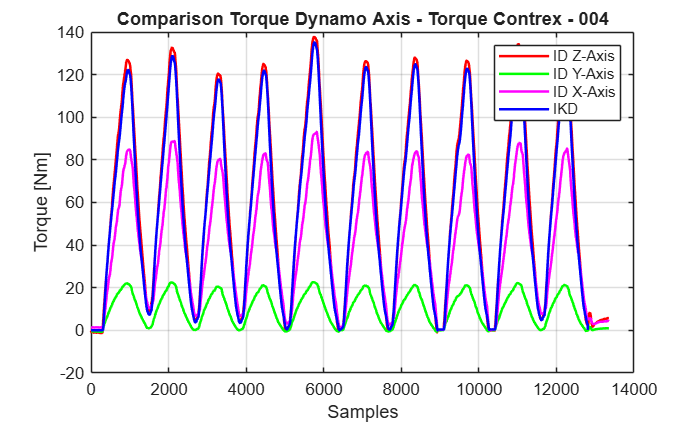

Torque_GRF_0404_x=Ankle_0404(3:end-1,3);
Torque_GRF_0404_y=Ankle_0404(3:end-1,4);
Torque_GRF_0404_z=Ankle_0404(3:end-1,5);
Torque_GRF_04_x=table2array(Torque_GRF_0404_x);
Torque_GRF_04_y=table2array(Torque_GRF_0404_y);
Torque_GRF_04_z=table2array(Torque_GRF_0404_z);

close all;
plot(Torque_GRF_04_z,'r','LineWidth',1.5);
hold on
plot(Torque_GRF_04_y,'g','LineWidth',1.5);
plot(Torque_GRF_04_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_100Hz_04(980:end),'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 004');
grid on;

## CODE ANKLE 05

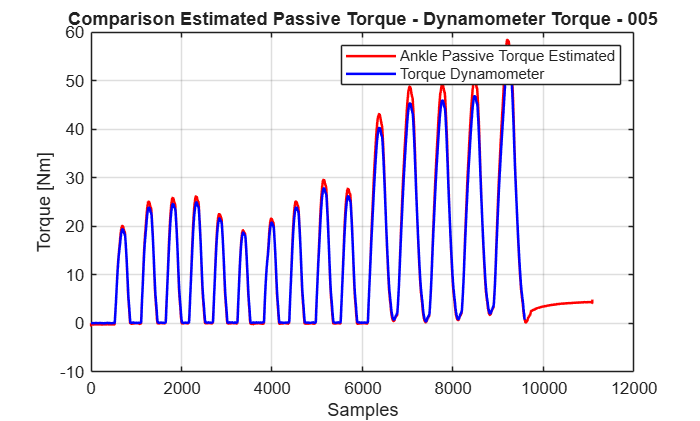

Fz_Ankle05_tab=Ankle_05(2:110791,5); 
LeverArm_Ankle05_tab=Ankle_05(110797:end,3);
Fz_Ankle05_original=table2array(Fz_Ankle05_tab); 
LeverArm_Ankle05=table2array(LeverArm_Ankle05_tab); 

Fz_Ankle05=resample(Fz_Ankle05_original, 100, 1000);

LeverArm_Ankle05=LeverArm_Ankle05./1000;
Torque_computed_Ankle05=Fz_Ankle05.*LeverArm_Ankle05;

Torque_dynamometer_original_05 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\005.cxp",...
    'FileType','text');
Torque_dynamometer_05=Torque_dynamometer_original_05(:,1);
Torque_dynamometer_100Hz_05 = resample(Torque_dynamometer_05, 100, 256);

close all;
plot(-Torque_computed_Ankle05-1.1,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_100Hz_05(3630:end),'b','LineWidth',1.5); 
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 005');
grid on;

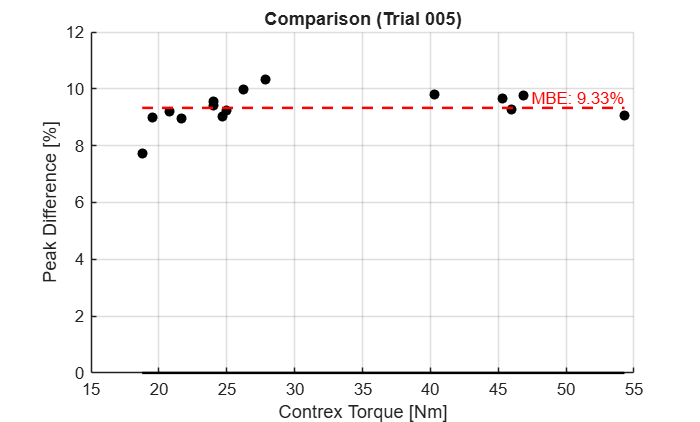

Torque_computed_Ankle05_Clean = abs(Torque_computed_Ankle05); 
Torque_dynamometer_100Hz_05_clean = abs(Torque_dynamometer_100Hz_05(3630:end));

min_len_05 = min(length(Torque_computed_Ankle05_Clean), length(Torque_dynamometer_100Hz_05_clean));
T_Est_05 = Torque_computed_Ankle05_Clean(1:min_len_05); 
T_Dyn_05 = Torque_dynamometer_100Hz_05_clean(1:min_len_05); 

[pks_dyn_05, locs_dyn_05] = findpeaks(T_Dyn_05, 'MinPeakHeight', 15, 'MinPeakDistance', 400); 
pks_est_05 = T_Est_05(locs_dyn_05); 

valid_indices_05 = pks_est_05 > 0 & pks_dyn_05 > 0;
Pks_Dyn_Final_05 = pks_dyn_05(valid_indices_05);
Pks_Est_Final_05 = pks_est_05(valid_indices_05);

Peak_Difference_05 = Pks_Est_Final_05 - Pks_Dyn_Final_05; 
Error_Percentage_Y_05 = (Peak_Difference_05 ./ Pks_Dyn_Final_05)  * 100;  
Dynamometer_Torque_X_05 = Pks_Dyn_Final_05;

figure;
scatter(Dynamometer_Torque_X_05, Error_Percentage_Y_05, 'k', 'filled'); 
hold on;

plot([min(Dynamometer_Torque_X_05) max(Dynamometer_Torque_X_05)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_05 = mean(Error_Percentage_Y_05);
plot([min(Dynamometer_Torque_X_05) max(Dynamometer_Torque_X_05)], [MBE_05 MBE_05], 'r--', 'LineWidth', 1.5); 

xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 005)');
grid on;
text(max(Dynamometer_Torque_X_05), MBE_05, sprintf('MBE: %.2f%%', MBE_05), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX - 05

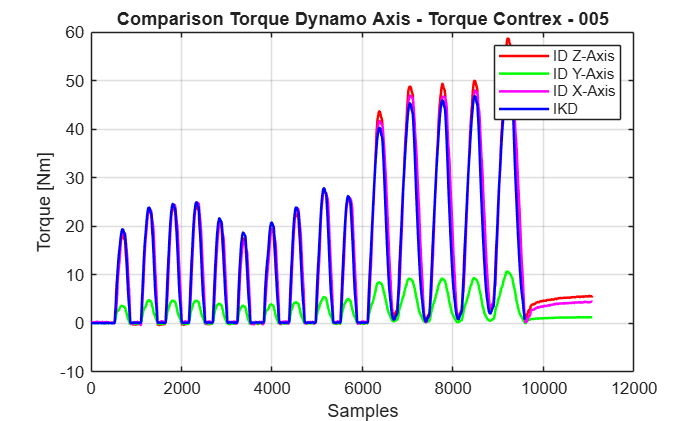

Torque_GRF_0505_x=Ankle_0505(3:end-1,3);
Torque_GRF_0505_y=Ankle_0505(3:end-1,4);
Torque_GRF_0505_z=Ankle_0505(3:end-1,5);
Torque_GRF_05_x=table2array(Torque_GRF_0505_x);
Torque_GRF_05_y=table2array(Torque_GRF_0505_y);
Torque_GRF_05_z=table2array(Torque_GRF_0505_z);

close all;
plot(Torque_GRF_05_z,'r','LineWidth',1.5);
hold on
plot(Torque_GRF_05_y,'g','LineWidth',1.5);
plot(Torque_GRF_05_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_100Hz_05(3630:end),'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 005');
grid on;

## CODE ANKLE 06

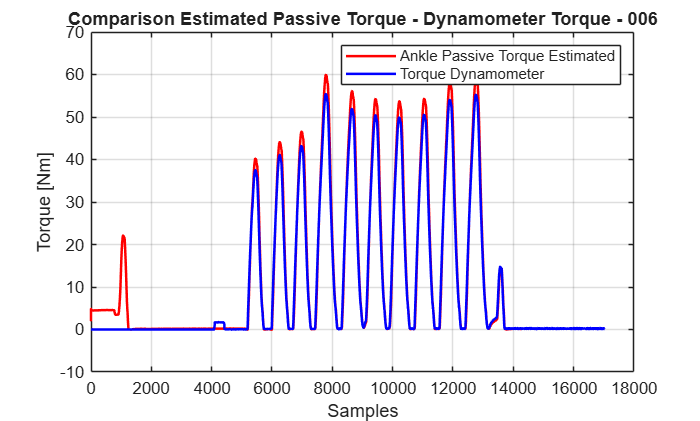

Fz_Ankle06_tab=Ankle_06(2:143091,5); 
LeverArm_Ankle06_tab=Ankle_06(143097:end,3);
Fz_Ankle06_original=table2array(Fz_Ankle06_tab); 
LeverArm_Ankle06=table2array(LeverArm_Ankle06_tab); 

Fz_Ankle06=resample(Fz_Ankle06_original, 100, 1000);

LeverArm_Ankle06=LeverArm_Ankle06./1000; 
Torque_computed_Ankle06=Fz_Ankle06.*LeverArm_Ankle06;

Torque_dynamometer_original_06 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\006.cxp",...
    'FileType','text');
Torque_dynamometer_06=Torque_dynamometer_original_06(:,1);
Torque_dynamometer_100Hz_06 = resample(Torque_dynamometer_06, 100, 256);

 N_06 = 4100; % samples for shift
 Torque_dynamometer_shifted_06 = [zeros(N_06,1); Torque_dynamometer_100Hz_06];

close all;
plot(-Torque_computed_Ankle06-1.1,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_shifted_06,'b','LineWidth',1.5); 
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 006');
grid on;

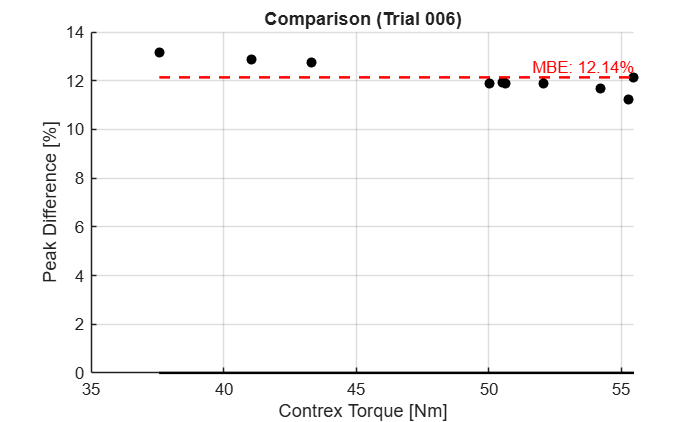

Torque_computed_Ankle06_Clean = abs(Torque_computed_Ankle06-1.1); 
Torque_dynamometer_shifted_06_clean = abs(Torque_dynamometer_shifted_06);

min_len_06 = min(length(Torque_computed_Ankle06_Clean), length(Torque_dynamometer_shifted_06_clean));
T_Est_06 = Torque_computed_Ankle06_Clean(1:min_len_06); 
T_Dyn_06 = Torque_dynamometer_shifted_06_clean(1:min_len_06); 

[pks_dyn_06, locs_dyn_06] = findpeaks(T_Dyn_06, 'MinPeakHeight', 35, 'MinPeakDistance', 600); 
pks_est_06 = T_Est_06(locs_dyn_06); 

valid_indices_06 = pks_est_06 > 0 & pks_dyn_06 > 0;
Pks_Dyn_Final_06 = pks_dyn_06(valid_indices_06);
Pks_Est_Final_06 = pks_est_06(valid_indices_06);

Peak_Difference_06 = Pks_Est_Final_06 - Pks_Dyn_Final_06; 

Error_Percentage_Y_06 = (Peak_Difference_06 ./ Pks_Dyn_Final_06)  * 100;  
Dynamometer_Torque_X_06 = Pks_Dyn_Final_06;

figure;
scatter(Dynamometer_Torque_X_06, Error_Percentage_Y_06, 'k', 'filled'); 
hold on;
plot([min(Dynamometer_Torque_X_06) max(Dynamometer_Torque_X_06)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_06 = mean(Error_Percentage_Y_06);
plot([min(Dynamometer_Torque_X_06) max(Dynamometer_Torque_X_06)], [MBE_06 MBE_06], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 006)');
grid on;
text(max(Dynamometer_Torque_X_06), MBE_06, sprintf('MBE: %.2f%%', MBE_06), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX - 06

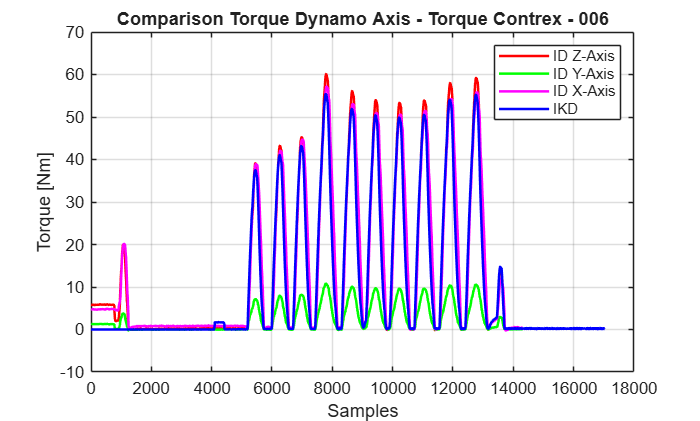

Torque_GRF_0606_x=Ankle_0606(3:end-1,3);
Torque_GRF_0606_y=Ankle_0606(3:end-1,4);
Torque_GRF_0606_z=Ankle_0606(3:end-1,5);
Torque_GRF_06_x=table2array(Torque_GRF_0606_x);
Torque_GRF_06_y=table2array(Torque_GRF_0606_y);
Torque_GRF_06_z=table2array(Torque_GRF_0606_z);

close all;
plot(Torque_GRF_06_z,'r','LineWidth',1.5);
hold on
plot(Torque_GRF_06_y,'g','LineWidth',1.5);
plot(Torque_GRF_06_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_shifted_06,'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 006');
grid on;

## CODE ANKLE 07

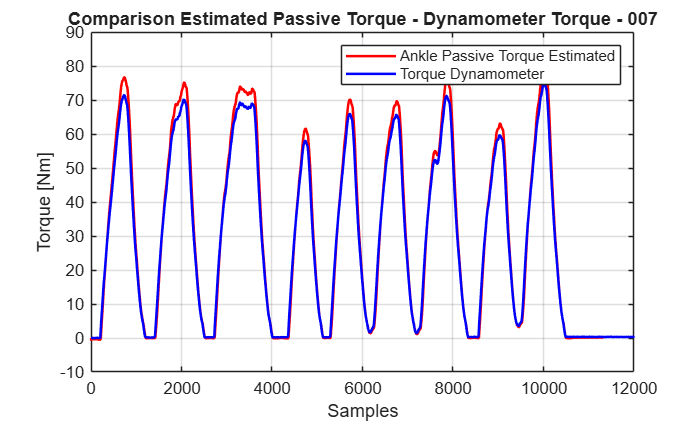

Fz_Ankle07_tab=Ankle_07(2:113191,5); 
LeverArm_Ankle07_tab=Ankle_07(113197:end,3);
Fz_Ankle07_original=table2array(Fz_Ankle07_tab); 
LeverArm_Ankle07=table2array(LeverArm_Ankle07_tab); 

Fz_Ankle07=resample(Fz_Ankle07_original, 100, 1000);

LeverArm_Ankle07=LeverArm_Ankle07./1000; 
Torque_computed_Ankle07=Fz_Ankle07.*LeverArm_Ankle07;

Torque_dynamometer_original_07 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\007.cxp",...
    'FileType','text');
Torque_dynamometer_07=Torque_dynamometer_original_07(:,1);
Torque_dynamometer_100Hz_07 = resample(Torque_dynamometer_07, 100, 256);

close all;
plot(-Torque_computed_Ankle07-1.3,'r','LineWidth',1.5);
hold on;
plot(-Torque_dynamometer_100Hz_07(1010:end),'b','LineWidth',1.5); 
legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Estimated Passive Torque - Dynamometer Torque - 007');
grid on;

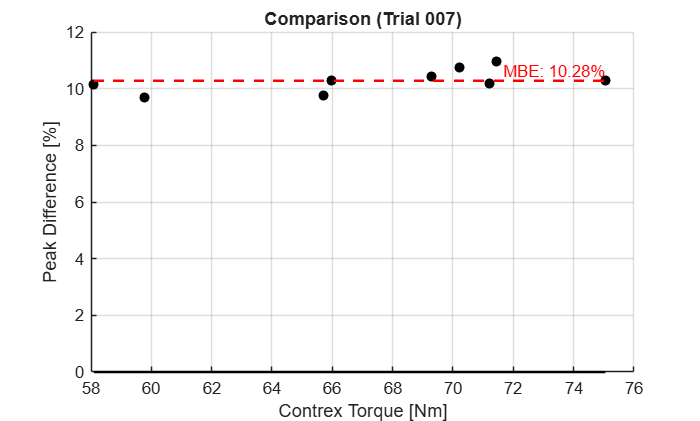

Torque_computed_Ankle07_Clean = abs(Torque_computed_Ankle07-1.3); 
Torque_dynamometer_100Hz_07_clean = abs(Torque_dynamometer_100Hz_07(1010:end));

min_len_07 = min(length(Torque_computed_Ankle07_Clean), length(Torque_dynamometer_100Hz_07_clean));
T_Est_07 = Torque_computed_Ankle07_Clean(1:min_len_07); 
T_Dyn_07 = Torque_dynamometer_100Hz_07_clean(1:min_len_07); 

[pks_dyn_07, locs_dyn_07] = findpeaks(T_Dyn_07, 'MinPeakHeight', 15, 'MinPeakDistance', 400); 
pks_est_07 = T_Est_07(locs_dyn_07); 

valid_indices_07 = pks_est_07 > 0 & pks_dyn_07 > 0;
Pks_Dyn_Final_07 = pks_dyn_07(valid_indices_07);
Pks_Est_Final_07 = pks_est_07(valid_indices_07);

Peak_Difference_07 = Pks_Est_Final_07 - Pks_Dyn_Final_07; 
Error_Percentage_Y_07 = (Peak_Difference_07 ./ Pks_Dyn_Final_07)  * 100;  
Dynamometer_Torque_X_07 = Pks_Dyn_Final_07;

figure;
scatter(Dynamometer_Torque_X_07, Error_Percentage_Y_07, 'k', 'filled'); 
hold on;
plot([min(Dynamometer_Torque_X_07) max(Dynamometer_Torque_X_07)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_07 = mean(Error_Percentage_Y_07);
plot([min(Dynamometer_Torque_X_07) max(Dynamometer_Torque_X_07)], [MBE_07 MBE_07], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 007)');
grid on;
text(max(Dynamometer_Torque_X_07), MBE_07, sprintf('MBE: %.2f%%', MBE_07), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX - 07

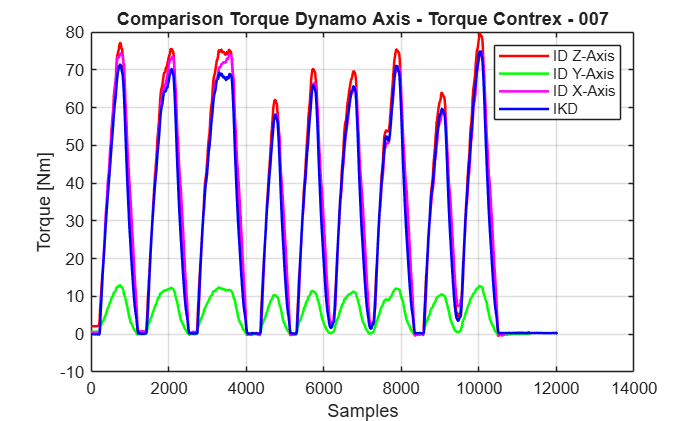

Torque_GRF_0707_x=Ankle_0707(3:end-1,3);
Torque_GRF_0707_y=Ankle_0707(3:end-1,4);
Torque_GRF_0707_z=Ankle_0707(3:end-1,5);
Torque_GRF_07_x=table2array(Torque_GRF_0707_x);
Torque_GRF_07_y=table2array(Torque_GRF_0707_y);
Torque_GRF_07_z=table2array(Torque_GRF_0707_z);

close all;
plot(Torque_GRF_07_z,'r','LineWidth',1.5);
hold on
plot(Torque_GRF_07_y,'g','LineWidth',1.5);
plot(Torque_GRF_07_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_100Hz_07(990:end),'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 007');
grid on;

## CODE ANKLE 08

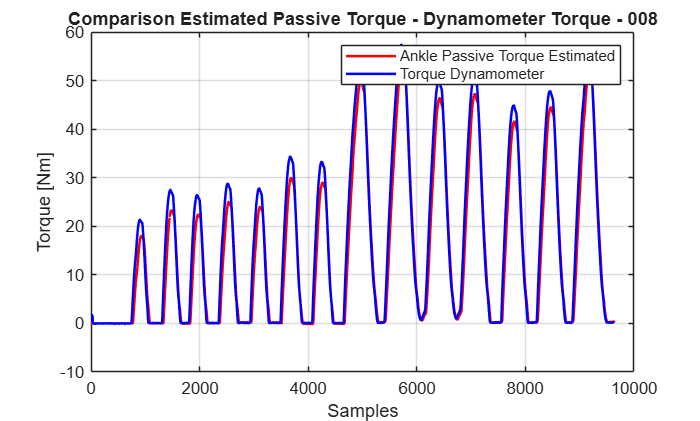

Fz_Ankle08_tab=Ankle_08(2:96501,5); 
LeverArm_Ankle08_tab=Ankle_08(96507:end,3);
Fz_Ankle08_original=table2array(Fz_Ankle08_tab); 
LeverArm_Ankle08=table2array(LeverArm_Ankle08_tab); 

Fz_Ankle08=resample(Fz_Ankle08_original, 100, 1000);

LeverArm_Ankle08=LeverArm_Ankle08./1000;
Torque_computed_Ankle08=Fz_Ankle08.*LeverArm_Ankle08;

Torque_dynamometer_original_08 = readmatrix("C:\Users\gabri\OneDrive\Desktop\HUS\Contrex_data\008.cxp",...
    'FileType','text');
Torque_dynamometer_08=Torque_dynamometer_original_08(:,1);
Torque_dynamometer_100Hz_08 = resample(Torque_dynamometer_08, 100, 256);

parte1_Ankle08=Torque_computed_Ankle08(1:1334);
parte2_Ankle08=Torque_computed_Ankle08(1340:3514)-min(Torque_computed_Ankle08(1675:1830)); %1335,3514
parte3_Ankle08=Torque_computed_Ankle08(3518:end)-min(Torque_computed_Ankle08(3910:4100)); 

Torque_corrected=[parte1_Ankle08;parte2_Ankle08;parte3_Ankle08];

 close all;
 plot(-Torque_corrected,'r','LineWidth',1.5); %Torque_corrected
 hold on;
 plot(-Torque_dynamometer_100Hz_08(330:9960),'b','LineWidth',1.5); 
 legend('Ankle Passive Torque Estimated', 'Torque Dynamometer');
 xlabel('Samples'); ylabel('Torque [Nm]');
 title('Comparison Estimated Passive Torque - Dynamometer Torque - 008');
 grid on;

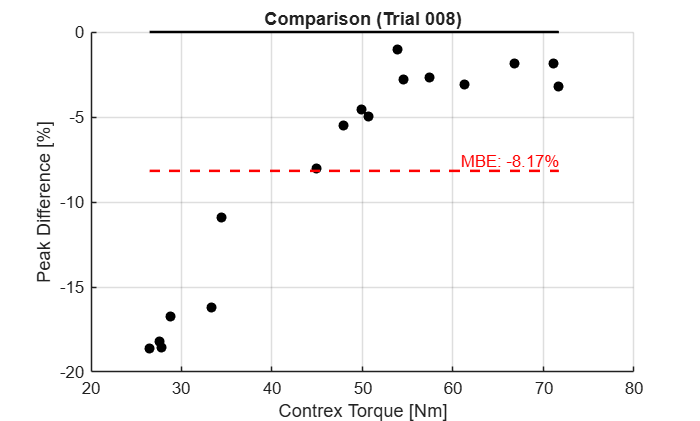

Torque_computed_Ankle08_Clean = abs(Torque_GRF_08_z); 
Torque_dynamometer_100Hz_08_clean = abs(Torque_dynamometer_100Hz_08(1420:end)); 

min_len_08 = min(length(Torque_computed_Ankle08_Clean), length(Torque_dynamometer_100Hz_08_clean));
T_Est_08 = Torque_computed_Ankle08_Clean(1:min_len_08); 
T_Dyn_08 = Torque_dynamometer_100Hz_08_clean(1:min_len_08); 

[pks_dyn_08, locs_dyn_08] = findpeaks(T_Dyn_08, 'MinPeakHeight', 15, 'MinPeakDistance', 400); 
pks_est_08 = T_Est_08(locs_dyn_08); 

valid_indices_08 = pks_est_08 > 0 & pks_dyn_08 > 0;
Pks_Dyn_Final_08 = pks_dyn_08(valid_indices_08);
Pks_Est_Final_08 = pks_est_08(valid_indices_08);

Peak_Difference_08 = Pks_Est_Final_08 - Pks_Dyn_Final_08; 
Error_Percentage_Y_08 = (Peak_Difference_08 ./ Pks_Dyn_Final_08)  * 100;  
Dynamometer_Torque_X_08 = Pks_Dyn_Final_08;

figure;
scatter(Dynamometer_Torque_X_08, Error_Percentage_Y_08, 'k', 'filled'); 
hold on;
plot([min(Dynamometer_Torque_X_08) max(Dynamometer_Torque_X_08)], [0 0], 'k-', 'LineWidth', 1.5); 
MBE_08 = mean(Error_Percentage_Y_08);
plot([min(Dynamometer_Torque_X_08) max(Dynamometer_Torque_X_08)], [MBE_08 MBE_08], 'r--', 'LineWidth', 1.5); 
xlabel('Contrex Torque [Nm]');
ylabel('Peak Difference [%]');
title('Comparison (Trial 008)');
grid on;
text(max(Dynamometer_Torque_X_08), MBE_08, sprintf('MBE: %.2f%%', MBE_08), 'VerticalAlignment', 'bottom',...
    'HorizontalAlignment', 'right', 'Color', 'r');

## GRF - CONTREX 08

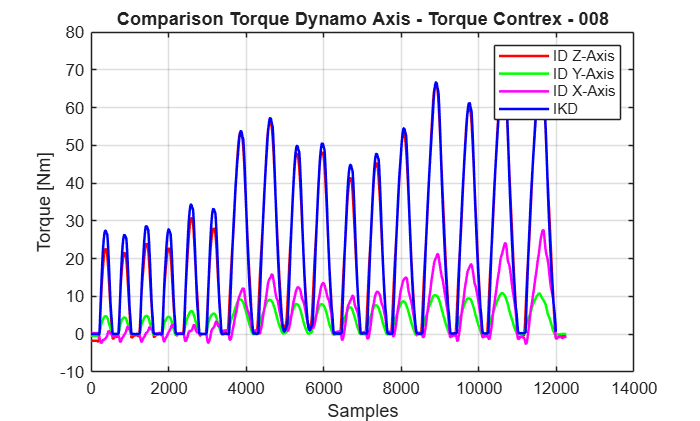

Torque_GRF_0808_1_x=Ankle_0808_1(3:end-1,3);
Torque_GRF_0808_2_x=Ankle_0808_2(3:end-1,3);
Torque_GRF_0808_1_y=Ankle_0808_1(3:end-1,4);
Torque_GRF_0808_2_y=Ankle_0808_2(3:end-1,4);
Torque_GRF_0808_1_z=Ankle_0808_1(3:end-1,5);
Torque_GRF_0808_2_z=Ankle_0808_2(3:end-1,5);

Torque_GRF_08_1_x=table2array(Torque_GRF_0808_1_x);
Torque_GRF_08_1_y=table2array(Torque_GRF_0808_1_y);
Torque_GRF_08_1_z=table2array(Torque_GRF_0808_1_z);
Torque_GRF_08_2_x=table2array(Torque_GRF_0808_2_x);
Torque_GRF_08_2_y=table2array(Torque_GRF_0808_2_y);
Torque_GRF_08_2_z=table2array(Torque_GRF_0808_2_z);

Torque_GRF_08_x=[Torque_GRF_08_1_x(1:3420);Torque_GRF_08_2_x]; 
Torque_GRF_08_y=[Torque_GRF_08_1_y(1:3420);Torque_GRF_08_2_y]; 
Torque_GRF_08_z=[Torque_GRF_08_1_z(1:3420);Torque_GRF_08_2_z]; 

close all;
plot(Torque_GRF_08_z,'r','LineWidth',1.5);
hold on
plot(Torque_GRF_08_y,'g','LineWidth',1.5);
plot(Torque_GRF_08_x,'m','LineWidth',1.5);
plot(-Torque_dynamometer_100Hz_08(1420:end),'b','LineWidth',1.5);
legend('ID Z-Axis','ID Y-Axis','ID X-Axis', 'IKD');
xlabel('Samples'); ylabel('Torque [Nm]');
title('Comparison Torque Dynamo Axis - Torque Contrex - 008');
grid on;